% Nathaniel Valla
% ESD II LAB 2

 
clc
clear

%% CONSTANTS
xNumPix = 752;   % total number of pixels in x direction of the sensor [px]
yNumPix = 480;
cx = xNumPix/2; cx_n = -cx; % camera x center
cy = yNumPix/2; cy_n = -cy; % camera y center
cyLeft = cy;     % left camera y center [px]
cxLeft = cx;     % left camera x center [px]
cyRight = cy;    % right camera y center [px]
cxRight = cx;    % right camera x center [px]
shift = 0:cx;    % shift

%% Indepedent Variables
dispair =170;     % dispair of Centroid
b =60;          % baseline [mm]
f =6;           % focal length [mm] 
ps = 0.006;      % pixel size [mm]
x_io = 102;
y_io = 95;
%% Dependent Variables 
xLeft = cxLeft*ones(size(shift)) -shift + x_io;
yLeft = y_io;
xRight = cxRight*ones(size(shift)) + x_io;
yRight = y_io;
zCenter = depth(xLeft,xRight,cxLeft,cxRight, b,f,ps);
xCenter = (zCenter .* (xLeft-cxLeft)*ps)/f;
yCenter = (zCenter .* (yLeft-cyLeft)*ps)/f;

fprintf("The centriod of the object is at (%d, %d. %d)", ...
         xCenter(dispair),yCenter(dispair),zCenter(dispair));

The centriod of the object is at (-2.378698e-02, -5.147929e-02. 3.550296e-01)

## Graphs

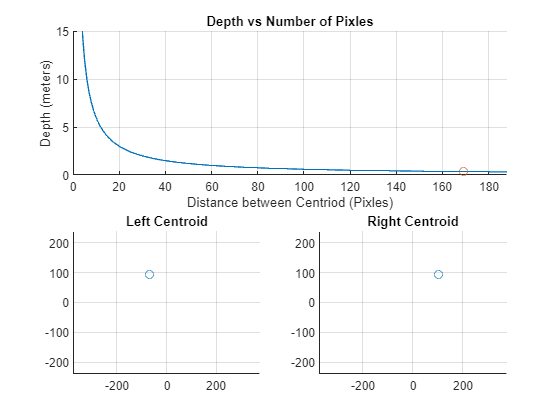

xMax = 188;
yMaxIdx = 5;

hold on
  subplot(2,2,[1,2])
  hold on
    title('Depth vs Number of Pixles')
    grid on
    plot(xRight-xLeft,zCenter);
    plot(xRight(dispair)-xLeft(dispair),zCenter(dispair),'o');
    xlabel("Distance between Centriod (Pixles)");
    ylabel("Depth (meters)");
    xlim([0,xMax]);
    ylim([0,zCenter(yMaxIdx)]);
  hold off
  subplot(2,2,3)
  hold on
    title('Left Centroid')
    grid on
    plot(xLeft(dispair)-cx,yLeft,'o');
    xlim([min(-cx),max(cx)]);
    ylim([min(-cy),max(cy)]);
  hold off
  subplot(2,2,4)
  hold on
    title('Right Centroid')
    grid on
    plot(xRight(dispair)-cx,yRight,'o');
    xlim([min(-cx),max(cx)]);
    ylim([min(-cy),max(cy)]);
  hold off
hold off

function Zm = depth(xLeft,xRight,cxLeft,cxRight, b,f,ps)
  d = (abs((xLeft-cxLeft)-(xRight-cxRight))*ps);  % disparity [mm]
  Zmm = (b * f)./d;       % depth [mm]
  Zm= Zmm./1000;          % depth [m]
end